Setup

format compact
clearvars
clc

Càrrega de variables

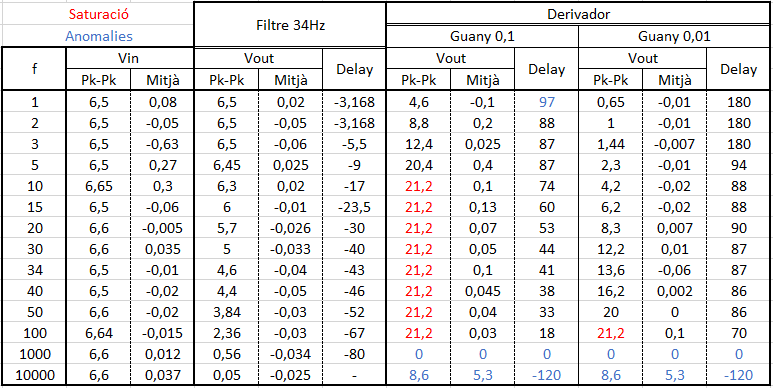

% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 12);

% Specify sheet, range, names and types
opts.Sheet = "Bodes Filtre i Derivador";
opts.DataRange = "B6:M19";
opts.VariableNames = ["f", "VinPkPk", "VinMitja", "VFilter34PkPk", "VFilter34Mitja", "FilterDelay", "VKd01PkPk", "VKd01Mitja", "VKd01Delay", "VKd001PkPk", "VKd001Mitja", "VKd001Delay"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data, convert and clean up
DadesBode = readtable("..\Dades en Llaç obert.xlsx", opts, "UseExcel", false);
DadesBode = table2array(DadesBode);
clear opts

Bode del filtre passabaixos de 34Hz

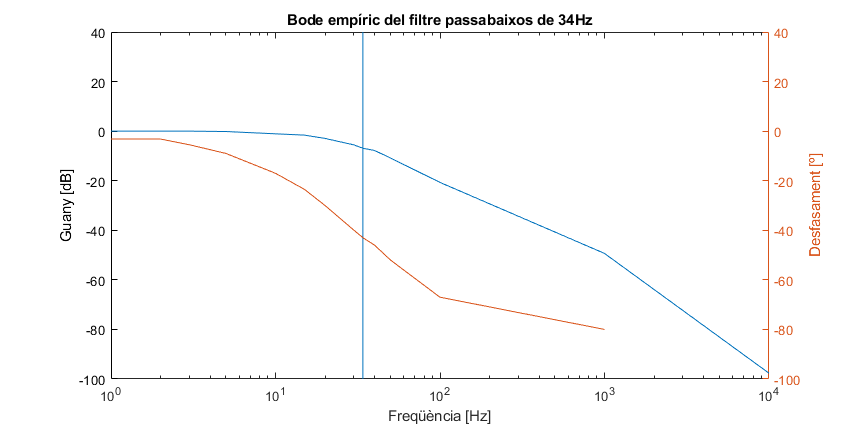

figure();
semilogx(DadesBode(:,1), 20*log(DadesBode(:,4)./DadesBode(:,2)));
ylabel('Guany [dB]');
xlabel('Freqüència [Hz]');
title('Bode empíric del filtre passabaixos de 34Hz');
axis([0 10000 -100 40]);
hold on;
line([34 34], [-100 40]);
yyaxis right;
plot(DadesBode(:,1), DadesBode(:,6));
axis([0 10000 -100 40]);
ylabel('Desfasament [º]');
hold off;

set(gcf,'units','pixels','position',[0,0,1920,963]);
exportgraphics(gcf, 'BodeFiltre34.png');

Bode del derivador

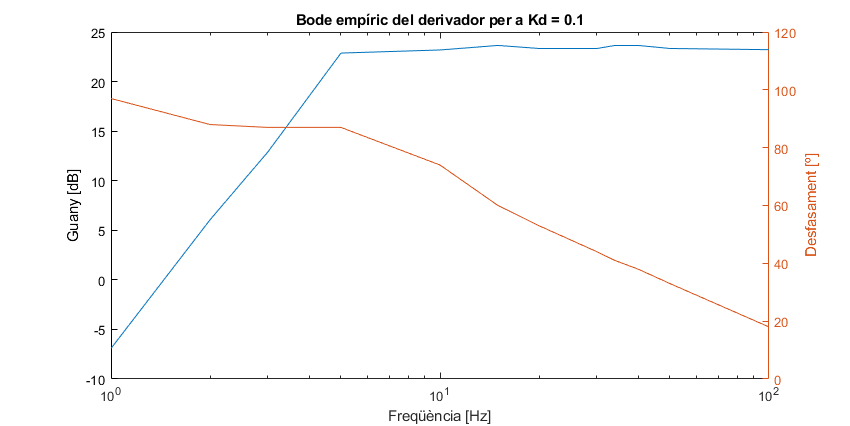

figure();
semilogx(DadesBode(1:(end-2),1), 20*log(DadesBode(1:(end-2),7)./DadesBode(1:(end-2),2)));
ylabel('Guany [dB]');
xlabel('Freqüència [Hz]');
title('Bode empíric del derivador per a Kd = 0.1');
%axis([0 100 -100 40]);
hold on;
yyaxis right;
plot(DadesBode(1:(end-2),1), DadesBode(1:(end-2),9));
axis([0 100 0 120]);
ylabel('Desfasament [º]');
hold off;

set(gcf,'units','pixels','position',[0,0,1920,963]);
exportgraphics(gcf, 'BodeKd01.png');

Bode del filtre passabaixos de 34Hz

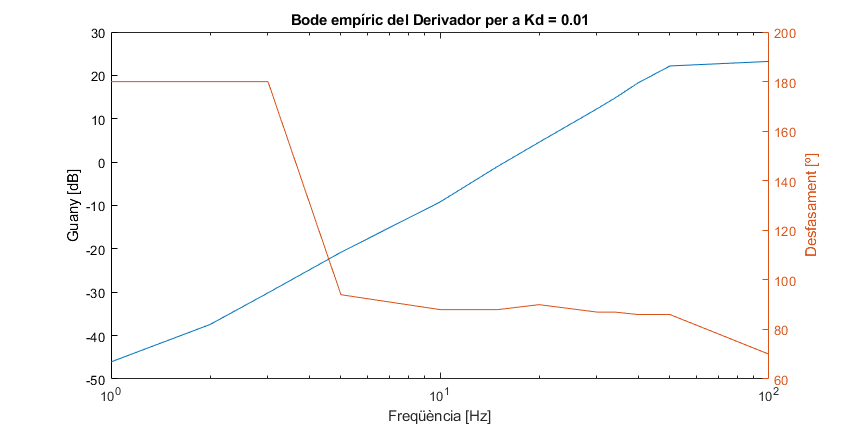

figure();
semilogx(DadesBode(1:(end-2),1), 20*log(DadesBode(1:(end-2),10)./DadesBode(1:(end-2),2)));
ylabel('Guany [dB]');
xlabel('Freqüència [Hz]');
title('Bode empíric del Derivador per a Kd = 0.01');
%axis([0 100 -100 40]);
hold on;
yyaxis right;
plot(DadesBode(1:(end-2),1), DadesBode(1:(end-2),12));
axis([0 100 60 200]);
ylabel('Desfasament [º]');
hold off;

set(gcf,'units','pixels','position',[0,0,1920,963]);
exportgraphics(gcf, 'BodeKd001.png');